clc
close all
clear
[x,fs] = audioread('data/230428-006-jump1-5m.wav')

x =   -0.002929687500000                   0
  -0.004699707031250                   0
  -0.003692626953125                   0
  -0.003479003906250                   0
  -0.005371093750000                   0
  -0.005218505859375   0.000030517578125
  -0.004974365234375  -0.000061035156250
  -0.004394531250000   0.000061035156250
  -0.006439208984375  -0.000061035156250
  -0.004364013671875   0.000091552734375


fs =        48000


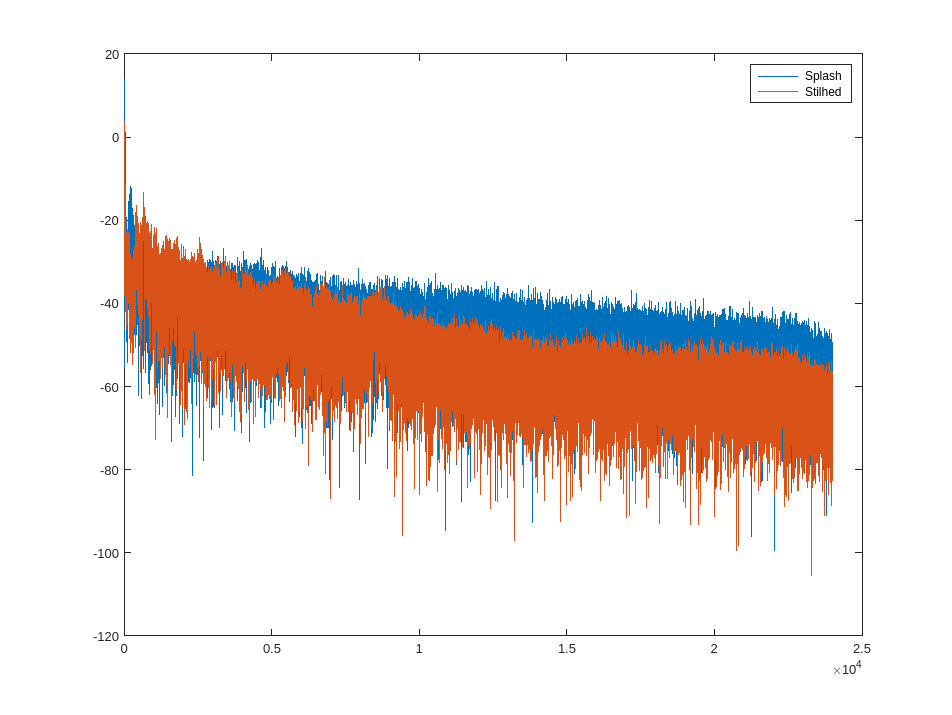

beningingOffset = 4*48000;
endOffset = 6*48000;

xSplask = x(beningingOffset:endOffset,1);
%sound(xSplask,fs)

xStilhed = x(17*48000:19*48000,1);
sound(xStilhed,fs)

[pxx,w] = periodogram(xSplask);
plot(w*fs/(2*pi),10*log10(pxx))
hold on
[pxxStilhed,wStilhed] = periodogram(xStilhed);
plot(wStilhed*fs/(2*pi),10*log10(pxxStilhed))
legend('Splash', 'Stilhed')
hold off